% load sensor.mat
load logsout/sensor4.mat

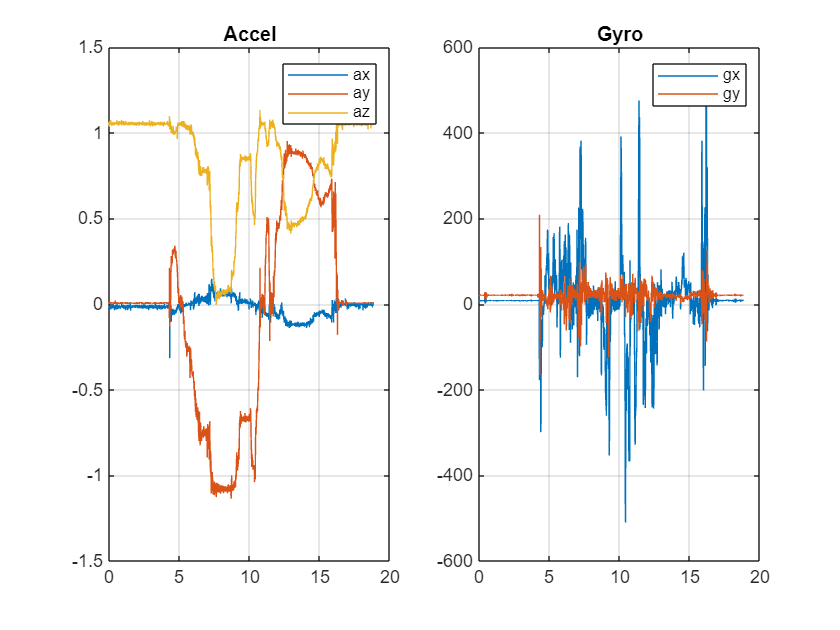

n_start = 10;
ax = find(logsout,'axf').Values.Data(n_start:end);
ay = find(logsout,'ayf').Values.Data(n_start:end);
az = find(logsout,'azf').Values.Data(n_start:end);

gx = find(logsout,'gxf').Values.Data(n_start:end);
gy = find(logsout,'gyf').Values.Data(n_start:end);
% gz = find(logsout,'gz').Values.Data(n_start:end);

tiltAngleRad = find(logsout,'tiltAngleToKalman').Values.Data(n_start:end,:);

sampleTime = 0.005;
N = length(ax);
t = [0:N-1]*sampleTime;

Q_kf = [0.0001 0 0 0;0 0 0 0;0 0 1E-5 0;0 0 0 0]*1000;
R_kf = [0.01 0;0 0.01]*1000;

figure()
subplot(1,2,1)
plot(t,ax)
hold on
plot(t,ay)
plot(t,az)
hold off
title('Accel')
legend('ax','ay','az')
grid on
subplot(1,2,2)
plot(t,gx)
hold on
plot(t,gy)
hold off
title('Gyro')
legend('gx','gy')
grid on

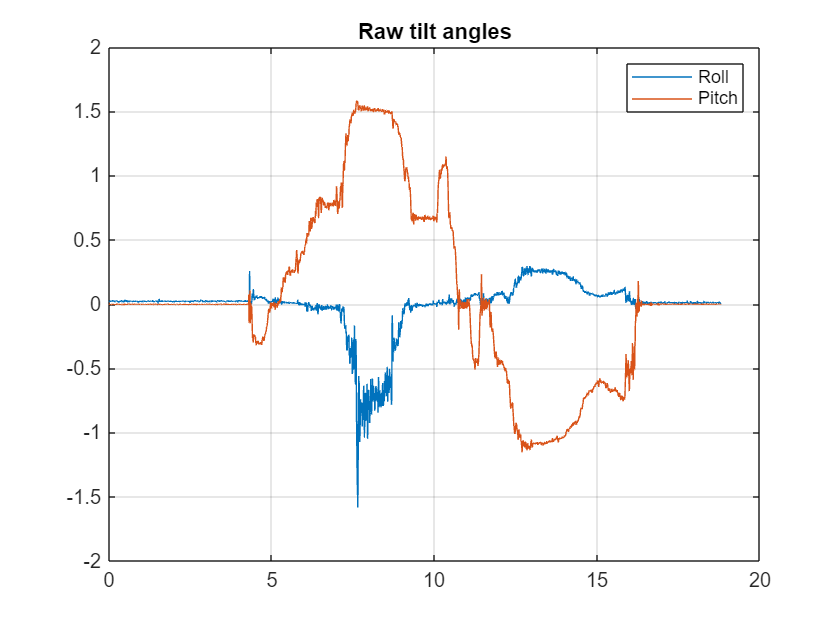


% From the function algorithm purely from the measurement Simulink
figure()
plot(t,tiltAngleRad)
title('Raw tilt angles')
legend('Roll','Pitch')
grid on

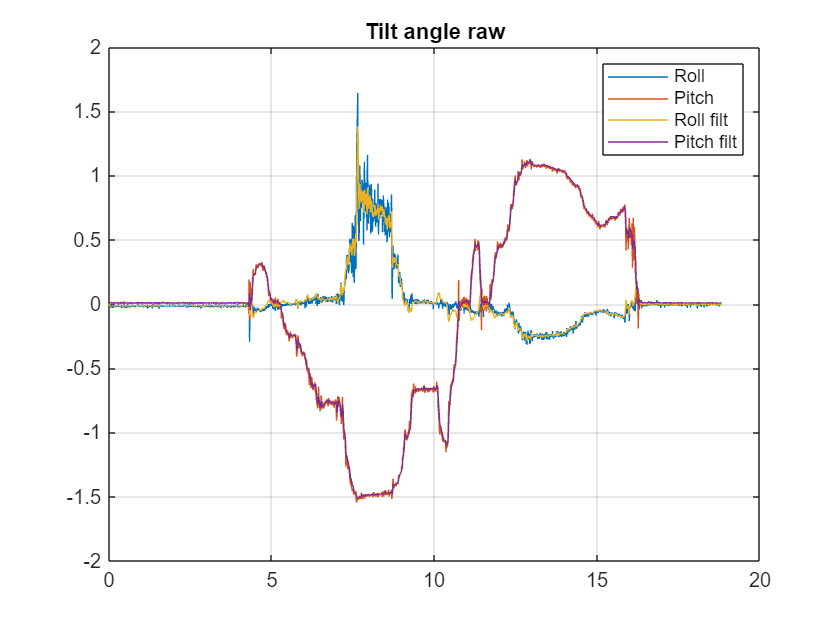




% Testing the complementary algorithm on the measurement
tiltAngle = zeros(N,2);
measRollPitch = zeros(N,3);
params = struct();
for i = 1:N
    [tiltAngle_temp,measRollPitch_temp] = compTiltFilter(ax(i), ay(i), az(i), gx(i), gy(i), sampleTime);
    tiltAngle(i,:) = tiltAngle_temp;
    measRollPitch(i,:) = measRollPitch_temp;
end

figure()
plot(t,measRollPitch(:,1:2))
hold on
plot(t,tiltAngle)
hold off
title('Tilt angle raw')
legend('Roll','Pitch','Roll filt','Pitch filt')
grid on

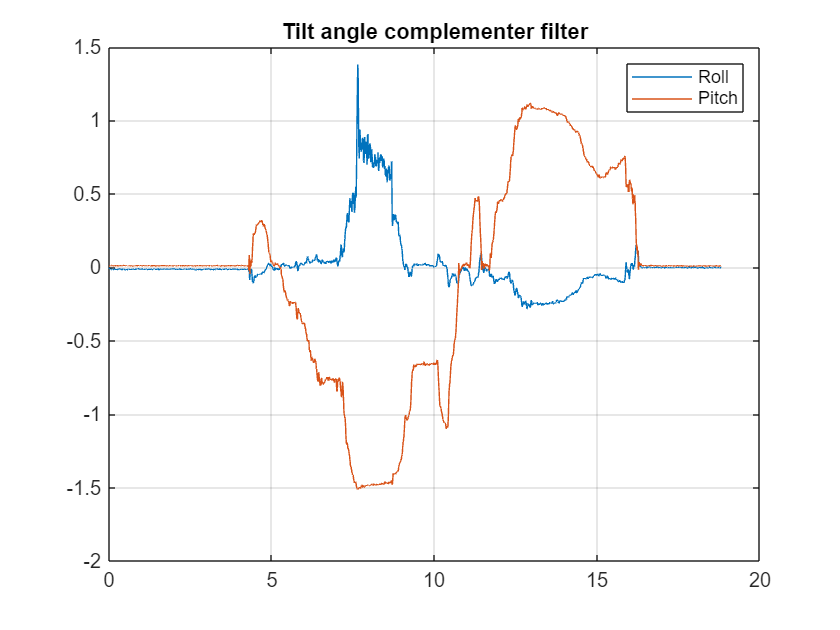


figure()
plot(t,tiltAngle)
title('Tilt angle complementer filter')
legend('Roll','Pitch')
grid on

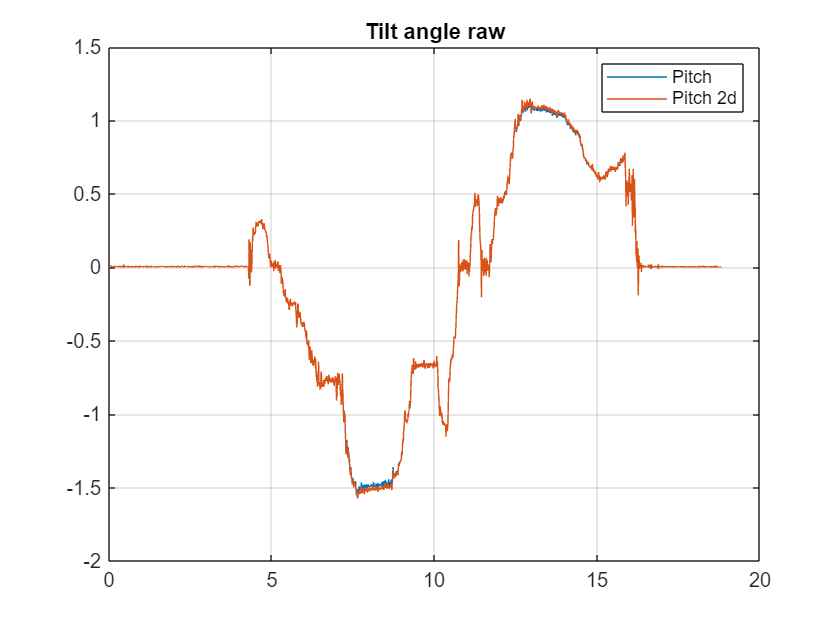


figure()
plot(t,measRollPitch(:,2:3))
title('Tilt angle raw')
legend('Pitch','Pitch 2d')
grid on

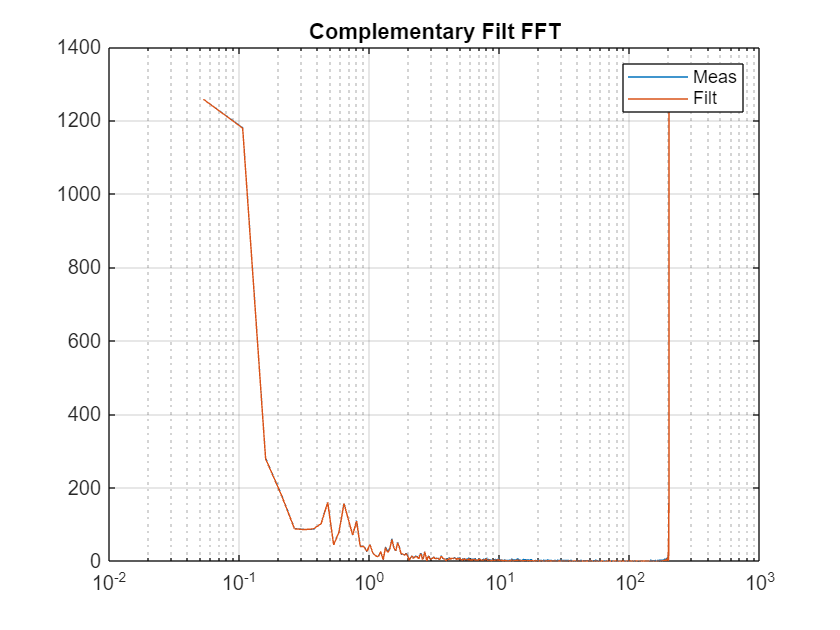


figure()
Y_meas = abs(fft(measRollPitch(:,2)));
Y_filt = abs(fft(tiltAngle(:,2)));
fs = 1/sampleTime;
f = [0:N-1]*fs/N;
semilogx(f,Y_meas,f,Y_filt)
legend('Meas','Filt')
title('Complementary Filt FFT')
grid on

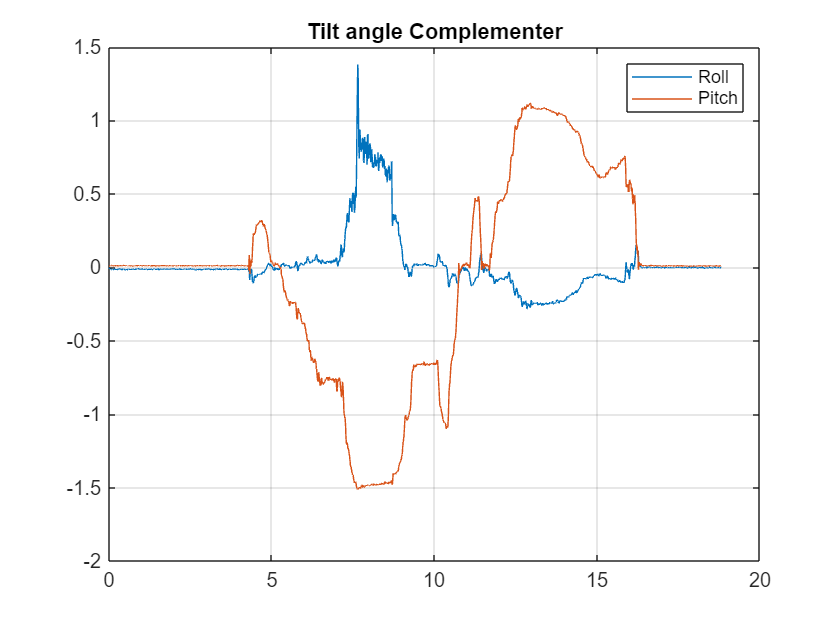

figure()
plot(t,tiltAngle)
title('Tilt angle Complementer')
legend('Roll','Pitch')
grid on

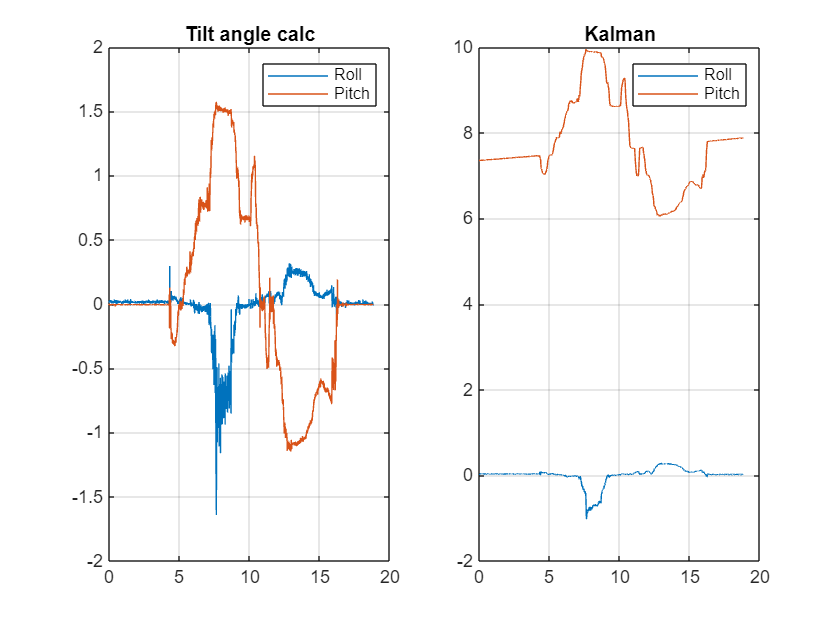

% Model 1
% Testing the algorithm on the measurement
tiltAngle = zeros(N,2);
measRollPitch = zeros(N,2);
for i = 1:N
    [tiltAngle_temp,measRollPitch_temp] = kalman2D(ax(i), ay(i), az(i), gx(i), gy(i), sampleTime,Q_kf,R_kf);
    tiltAngle(i,:) = tiltAngle_temp;
    measRollPitch(i,:) = measRollPitch_temp;
end

figure()
subplot(1,2,1)
plot(t,measRollPitch)
title('Tilt angle calc')
legend('Roll','Pitch')
grid on
subplot(1,2,2)
plot(t,tiltAngle)
title('Kalman')
legend('Roll','Pitch')
grid on

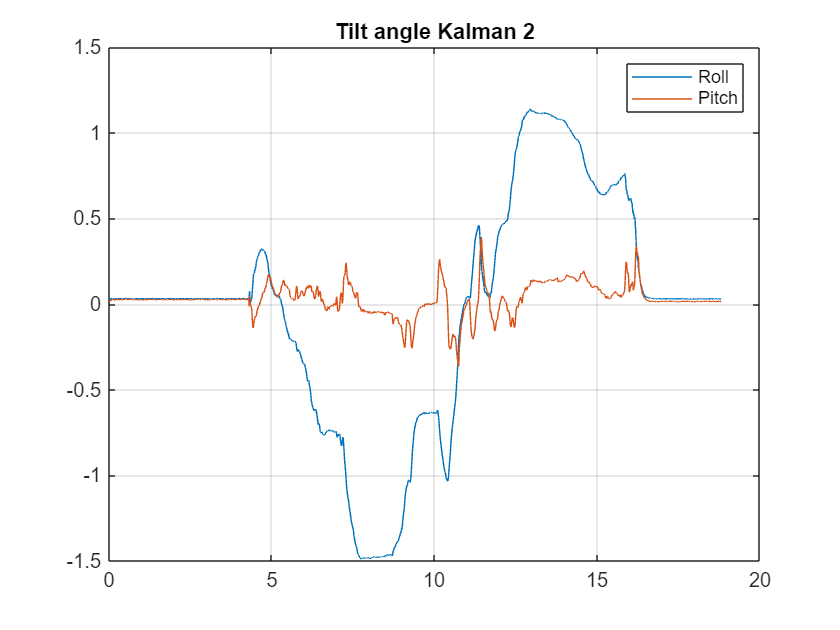


% Model 2
measRollPitch2 = zeros(N,2);
for i = 1:N
    y = kalman_orientation_ekf(ax(i), ay(i), az(i), gx(i), gy(i),sampleTime);
    measRollPitch2(i,:) = y;
end

figure()
plot(t,measRollPitch2)
title('Tilt angle Kalman 2')
legend('Roll','Pitch')
grid on